# Lab 8 - Pseudo-experiment data analysis

Requires knowing how to do Lab 7 to proceed.

clc; clear; close all;
% h5disp("data_lowLumi_pt_1000_1200.h5");
% h5disp("data_highLumi_pt_1000_1200.h5");
highitems = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_items');
highvalues = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
lowitems = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_items');
lowvalues = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');
signal = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bg = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
% are expected yields the same, nhiggs = 50 and nqcd = 2000?

## Problem 1 - High luminosity data

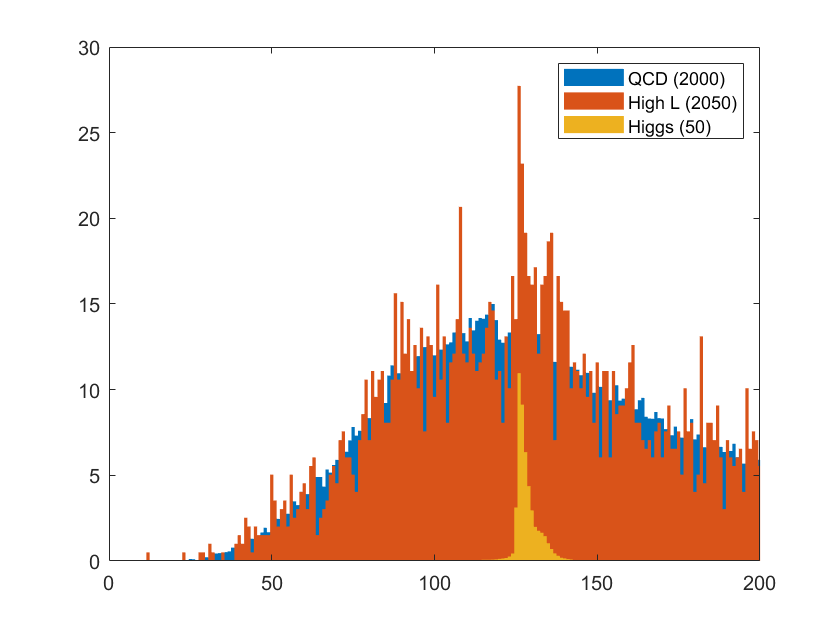

x = 0:1:800;
%histogram(highvalues(4,:),x,"EdgeColor","none");
f1 = figure();
f2 = figure("Visible","off");
h = histogram(signal(4,:),x,"Normalization","pdf","EdgeColor","none");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg(4,:),x,"Normalization","pdf","EdgeColor","none");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
h3 = histogram(highvalues(4,:),x,"Normalization","pdf","EdgeColor","none");
h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
hold off;

figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + sum(h2.BinCounts) + ")","High L (2050)","Higgs (50)");
xlim([0,200]);
hold off;

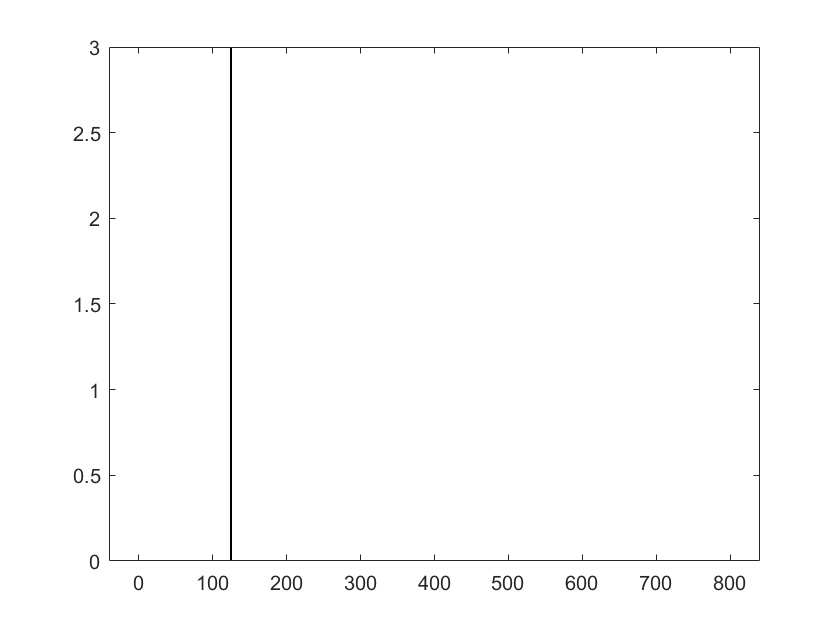

% h2.BinCounts = zeros(199,1) + h2.BinCounts(200:800);

lowercut = 124.99;
uppercut = 125.01;
cuthighvalues = highvalues(4,highvalues(4,:) < uppercut);
cuthighvalues = cuthighvalues(cuthighvalues > lowercut);
cutsignal = signal(4,signal(4,:) < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(4,bg(4,:) < uppercut);
cutbg = cutbg(cutbg > lowercut);

histogram(cuthighvalues,x); % to do


nhiggs = numel(cutsignal)/numel(signal(4,:))*50

nhiggs = 3.2850

nqcd = numel(cutbg)/numel(bg(4,:))*2000

nqcd = 0.1800

nhighl = numel(cuthighvalues)/numel(highvalues(4,:)) * 2050

nhighl = 2.0167

nhiggs/sqrt(nqcd)

ans = 7.7428

nhighl/sqrt(nqcd)

ans = 4.7535

## Problem 2

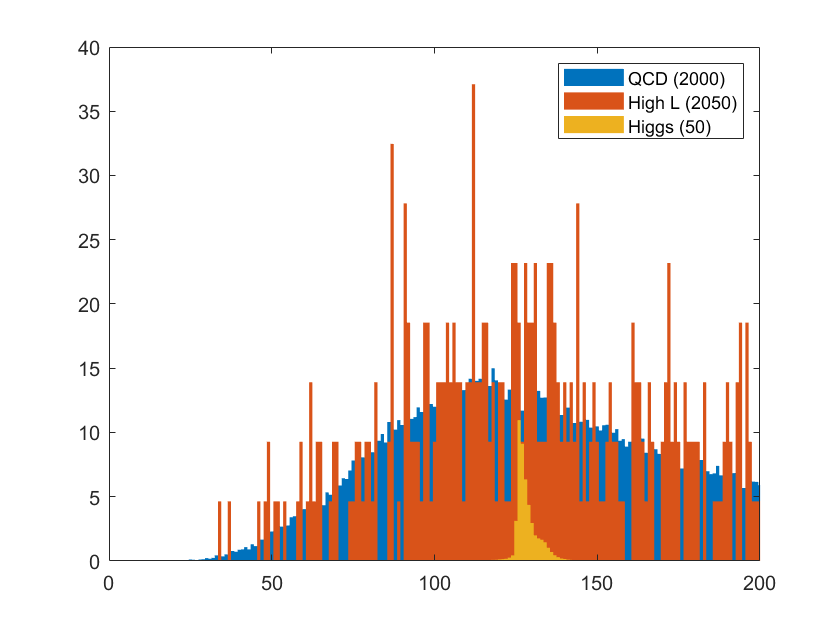

x = 0:1:800;
f1 = figure();
f2 = figure("Visible","off");
h = histogram(signal(4,:),x,"Normalization","pdf","EdgeColor","none");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg(4,:),x,"Normalization","pdf","EdgeColor","none");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
h3 = histogram(lowvalues(4,:),x,"Normalization","pdf","EdgeColor","none");
h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
hold off;

figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + sum(h2.BinCounts) + ")","High L (2050)","Higgs (50)");
xlim([0,200]);
hold off;

cutlowvalues = lowvalues(4,lowvalues(4,:) < uppercut);
cutlowvalues = cutlowvalues(cutlowvalues > lowercut);
nlowl = numel(cutlowvalues)/numel(lowvalues(4,:)) * 2050

nlowl = 0

nlowl/sqrt(nqcd)

ans = 0